# Kannan Paper ODEs

Simulate models from Kannan paper.

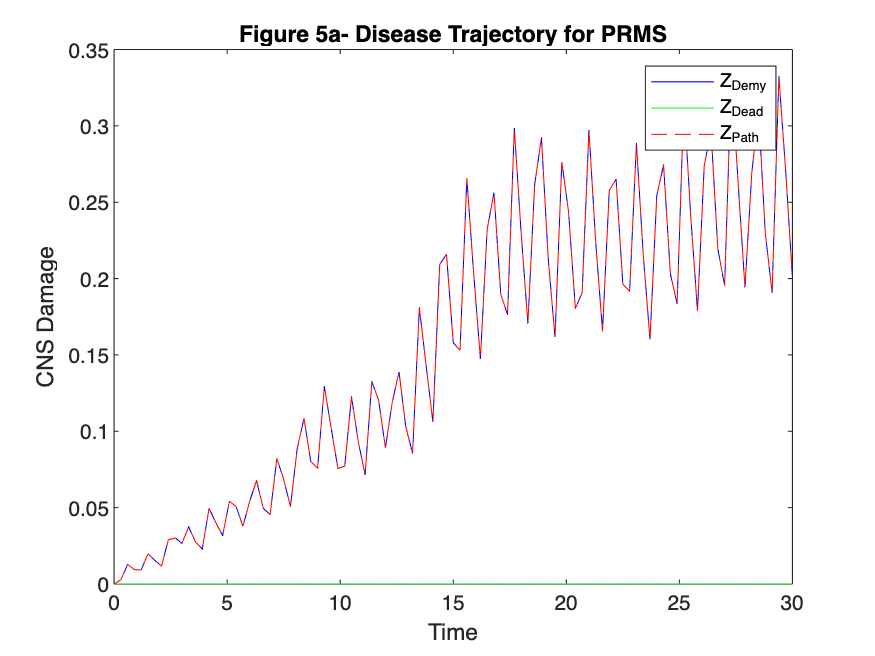

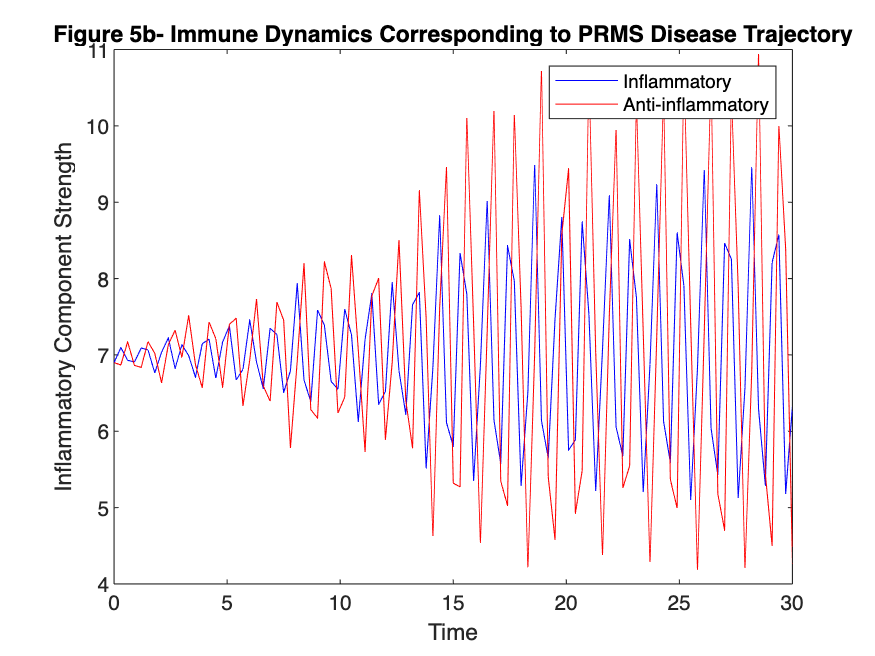

clc;
clear;
scenario = "5";
%ODEs for the model are given by Eqns 1-5

%Time Range
tinitial=0;
tfinal=30;
numberOfTimes = 101;
t=linspace(tinitial, tfinal, numberOfTimes);
%Initial Conditions
Ci=[6.8989 6.8989 0 0];

if strcmp(scenario, "2")

fig=2;
soln=ode45(@(t,Ci)ODEs(t,Ci,fig),t,Ci);

I=deval(soln,t, 1);
A=deval(soln,t,2);
Z_Demy=deval(soln,t,3);
Z_Dead=deval(soln,t,4);
Z_Path=Z_Demy+Z_Dead;

%Figure 2a
%In this figure disease pathology(Eqn 5) is equivalent to demyelination(Eqn 3)
%Dead cells are represented by (Eqn 4), there are no dead cells

figure(1)
plot(t,Z_Demy,'b-')
  xlabel('Time'), ylabel('CNS Damage'), title('Figure 2a- Disease Trajectory for RRMS')
  hold on 
  plot(t,Z_Dead,'g-')
  plot(t,Z_Path,'r--')
  legend('Z_{Demy}', 'Z_{Dead}', 'Z_{Path}')
  hold off

%Figure 2b
%This figure shows the corresponding disease dynamics for RRMS
figure(2)
plot(t,I,'b')
  xlabel('Time'), ylabel('Inflammatory Component Strength'), title('Figure 2b- Immune Dynamics Corresponding to RRMS Disease Trajectory')
  hold on 
  plot(t,A,'r')
  legend('Inflammatory', 'Anti-inflammatory')
  hold off

elseif strcmp(scenario,"3")
%Figure 3a
%Initial Conditions

fig=3;
soln=ode45(@(t,Ci)ODEs(t,Ci,fig),t,Ci);

I=deval(soln,t, 1);
A=deval(soln,t,2);
Z_Demy=deval(soln,t,3);
Z_Dead=deval(soln,t,4);
Z_Path=Z_Demy+Z_Dead;

figure(1)
plot(t,Z_Demy,'b-')
  xlabel('Time'), ylabel('CNS Damage'), title('Figure 3a- Disease Trajectory for SPMS')
  hold on 
  plot(t,Z_Dead,'g-')
  plot(t,Z_Path,'r--')
  legend('Z_{Demy}', 'Z_{Dead}', 'Z_{Path}')
  hold off

%Figure 3b
%This figure shows the corresponding immune system dynamics for SPMS
figure(2)
plot(t,I,'b')
  xlabel('Time'), ylabel('Inflammatory Component Strength'), title('Figure 3b- Immune Dynamics Corresponding to SPMS Disease Trajectory')
  hold on 
  plot(t,A,'r')
  legend('Inflammatory', 'Anti-inflammatory')
  hold off

elseif strcmp(scenario,"4")
%Figure 4a
%This figure shows the disease trajectory for PPMS
fig=4;
soln=ode45(@(t,Ci)ODEs(t,Ci,fig),t,Ci);

I=deval(soln,t, 1);
A=deval(soln,t,2);
Z_Demy=deval(soln,t,3);
Z_Dead=deval(soln,t,4);
Z_Path=Z_Demy+Z_Dead;

figure(1)
plot(t,Z_Demy,'b-')
  xlabel('Time'), ylabel('CNS Damage'), title('Figure 4a- Disease Trajectory for PPMS')
  hold on 
  plot(t,Z_Dead,'g-')
  plot(t,Z_Path,'r--')
  legend('Z_{Demy}', 'Z_{Dead}', 'Z_{Path}')
  hold off

%Figure 4b
%This figure shows the corresponding immune system dynamics for PPMS
figure(2)
plot(t,I,'b')
  xlabel('Time'), ylabel('Inflammatory Component Strength'), title('Figure 4b- Immune Dynamics Corresponding to PPMS Disease Trajectory')
  hold on 
  plot(t,A,'r')
  legend('Inflammatory', 'Anti-inflammatory')
  hold off

elseif strcmp(scenario,"5")
%Figure 5a
%This figure shows the disease trajectory for PRMS
fig=5;
soln=ode45(@(t,Ci)ODEs(t,Ci,fig),t,Ci);

I=deval(soln,t, 1);
A=deval(soln,t,2);
Z_Demy=deval(soln,t,3);
Z_Dead=deval(soln,t,4);
Z_Path=Z_Demy+Z_Dead;

figure(1)
plot(t,Z_Demy,'b-')
  xlabel('Time'), ylabel('CNS Damage'), title('Figure 5a- Disease Trajectory for PRMS')
  hold on 
  plot(t,Z_Dead,'g-')
  plot(t,Z_Path,'r--')
  legend('Z_{Demy}', 'Z_{Dead}', 'Z_{Path}')
  hold off

%Figure 5b
%This figure shows the corresponding immune system dynamics for PRMS
figure(2)
plot(t,I,'b')
  xlabel('Time'), ylabel('Inflammatory Component Strength'), title('Figure 5b- Immune Dynamics Corresponding to PRMS Disease Trajectory')
  hold on 
  plot(t,A,'r')
  legend('Inflammatory', 'Anti-inflammatory')
  hold off
end


function derivVector=ODEs(t,y,fig)
%Parameters given in Table 1
%Controls rate of change of inflammatory component
c1=20;
b1=30;
%Stationary state value of pro and anti inflammatory components
Is=7;
As=7;
%Initial increase rate of inflammatory component upon immune breach
zeta0=0.5;
%Time scale for inflammatory component proliferation following immune breach
tau=20;
%Poisson rate at which random perturbations occur
lambda=20;
%Ic represents immune threshold, varies
%Controls rate of change of anti-inflammatory component
c2=50;
b2=30;
%Controls rate of change of demyelination
c3=20;
b3=40;
%Total volume of region susceptible to damage
Ztot=2;
%Rate of remyelination
k=1;
%Controls the growth of dead cells
c4=0.5;
%CNS threshold, Zc varies

I=y(1);
A=y(2);
Z_Demy=y(3);
Z_Dead=y(4);

if fig==2
%Figure 2 values
Ic=25;
Zc=4;

elseif fig==3
%Figure 3 values
Ic=13;
Zc=4;

elseif fig==4
%Figure 4 values
Ic=9;
Zc=1.2;

elseif fig==5
%Figure 5 values
Ic=20;
Zc=0.4;
end

%tc is unknown, guess tc
tc=20;

dI_dt= -1*c1*I*((A-As)/(b1+A))*heaviside(Ic-I)+zeta0*exp((t-tc)/tau)*heaviside(I-Ic)+Flambda(t);
dA_dt= c2*A*((I-Is)/(b2+I))*heaviside(Ic-I);
dZDemy_dt= (c3*((I-Is)/(b3+I))*((Ztot-Z_Demy-Z_Dead)/Ztot)*heaviside(I-Is))-(k*Z_Demy);
dZDead_dt= c4*((Ztot-Z_Dead)/Ztot)*heaviside(Z_Demy-Zc);

derivVector = [dI_dt, dA_dt, dZDemy_dt, dZDead_dt]';
end

%New Stochastic Noise Function from 3/28 Meeting
function y = Flambda(t)
% Parameters
lambda = 20; % Event rate (average occurrences per unit time)
time_end = 25; % Simulation end time (match graph's x-axis)
delta_t = 0.01; % Time step (fine resolution for fluctuations) %This can be changed 
offset = 0 ; % Adjust offset to center fluctuations within the desired range

% Generate Poisson-distributed event times
num_events = poissrnd(lambda * time_end); % Total events based on lambda
event_times = sort(rand(num_events, 1) * time_end); % Event times

% Generate random values for v_i (adjust amplitude range)
a=-20;
b=20;
v_i = a + (b - a) * rand(num_events, 1); % Uniform distribution U[-20, 20] %this can be changed

% Time vector
time_vector = 0:delta_t:time_end;

% Compute F_i(t)
F_t = zeros(size(time_vector));
for i = 1:num_events
    % Find the nearest time bin for event time t_i
    [~, idx] = min(abs(time_vector - event_times(i)));
    F_t(idx) = F_t(idx) + v_i(i);
end

% Add offset to center the fluctuations
F_t = F_t + offset;

% % Optional: Smooth the curve to refine jaggedness
%F_t_smooth = smooth(F_t, 5); % Moving average filter

rounding_decimals = 2; %This can be changed
index = find(time_vector==round(t,rounding_decimals));
if isempty(index) == 1
    y = 0;
else
    y = F_t(index);
end
end

%Original Stochastic Noise Function
% function y= Flambda(t,lambda)
% %Uniform distribution U[-0.1 0.1]
% a= -0.1;
% b= 0.1;
% %Guess that imax=100
% imax=100;
% output=0;
% eps=1e-3;
% for i=1:imax
%     vi=a+(b-a)*rand;
%     ti=poissrnd(lambda);
%    if abs(t-ti)<eps
%        output=output+vi;
%    end
%    y=output;
% end
% end